# Double Integrator Reach-Avoid Via Dynamic Programming

This example demonstrates how to use the SReachTools toolbox to solve a terminal-hitting time reach-avoid problem using [dynamic programming](https://doi.org/10.1016/j.automatica.2010.08.006).

In this example, we analyze the following problems via dynamic programming for a stochastic system with known dynamics:

- **stochastic viability problem: **Compute a controller to stay within a safe set with maximum likelihood

- **the terminal-hitting time stochastic reach-avoid problem: **Compute a controller that maximizes the probability of reaching a target set at a time horizon, `N`, while maintaining the system in a set of safe states

- **stochastic reachability of a moving target tube: **Compute a controller that maximizes the probability of staying within a target tube

- **the first-hitting time stochastic reach-avoid problem: **Compute a controller that maximizes the probability of reaching a target set within the time horizon, `N`, while maintaining the system in a set of safe states

SReachTools has a dynamic programing implementation that can analyze systems upto three dimensions. For efficient implementation, we require the input set to be an axis-aligned hypercuboid, and define the grid the smallest hypercuboid containing all the target sets.

## Notes about this Live Script:

- **MATLAB dependencies**: This Live Script uses MATLAB's  [Statistics and Machine Learning Toolbox](https://www.mathworks.com/products/statistics.html). 

- **External dependencies**: This Live Script uses Multi-Parameteric Toolbox ([MPT](http://people.ee.ethz.ch/~mpt/3/)). 

- Make sure that `srtinit` is run before running this script.

This Live Script is part of the SReachTools toolbox. License for the use of this function is given in [https://github.com/unm-hscl/SReachTools/blob/master/LICENSE](https://github.com/unm-hscl/SReachTools/blob/master/LICENSE).

# Problem setup

## Double Integrator

In this example we use a discretized double integrator dynamics given by:


$$  x_{k+1} = \left[ \begin{array}{cc}
    1 & T \\
    0 & 1
  \end{array}\right] x_{k} + \left[\begin{array}{c}
    \frac{T^{2}}{2} \\
    T
  \end{array}\right] u_{k} + w_{k}$$


where $T$ is the discretization time-step, and $w_{k}$ is the stochastic disturbance.

## Setup the system

% discretization parameter
T = 0.1;

% define the system
sys = LtiSystem('StateMatrix', [1, T; 0, 1], ...
    'InputMatrix', [T^2/2; T], ...
    'InputSpace', Polyhedron('lb', -0.1, 'ub', 0.1), ...
    'DisturbanceMatrix', eye(2), ...
    'Disturbance', StochasticDisturbance('Gaussian', zeros(2,1), 0.01*eye(2)));

## Setup the dynamic programming and visualization parameters

dyn_prog_xinc = 0.05;
dyn_prog_uinc = 0.1;
reach_set_thresholds = [0.2 0.5 0.9];
legend_str={'Safety tube at t=0', 'Safety Probability $\geq 0.2$', 'Safety Probability $\geq 0.5$', 'Safety Probability $\geq 0.9$'};

# Case 1: Stochastic viability problem

## Setup the target and safe sets

safe_set = Polyhedron('lb', [-1, -1], 'ub', [1, 1]);
axis_vec1 = [-1 1 -1 1];

## Setup the target tube

Safety tube is a generalization of the reach problem. The reach avoid target-tube is created by setting the first $N-1$ sets in the tube as the `safe_set` and the final set as the `target_set`.

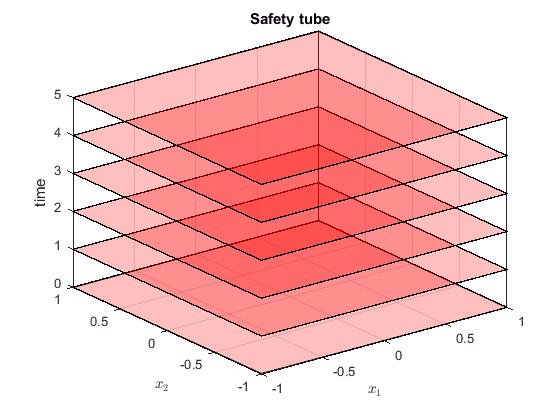

% time horizon
N = 5;
% in target tube for the viability problem is equivalent to a tube of repeating
% safe sets
safety_tube1 = TargetTube('viability', safe_set, N);

% Plotting of safety tube
figure()
hold on    
for time_indx=0:N
    safety_tube_at_time_indx = Polyhedron('H',[safety_tube1(time_indx+1).A,zeros(size(safety_tube1(time_indx+1).A,1),1), safety_tube1(time_indx+1).b], 'He',[0 0 1 time_indx]);
    plot(safety_tube_at_time_indx, 'alpha',0.25);
end
axis([axis_vec1 0 N])
box on;
grid on;
xlabel('$x_1$','interpreter','latex');
ylabel('$x_2$','interpreter','latex');
zlabel('time');
title('Safety tube');

## Dynamic programming recursion via gridding

tic;
[prob_x1, cell_of_xvec_x1] =  SReachDynProg('term', sys, dyn_prog_xinc, dyn_prog_uinc, safety_tube1);
toc

Elapsed time is 3.117079 seconds.


## Visualization of the value function at t=0 (safety probability)

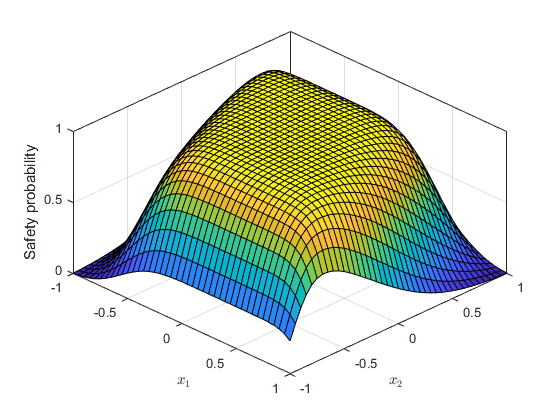

figure();
x1vec = cell_of_xvec_x1{1};
x2vec = cell_of_xvec_x1{2};
surf(x1vec,x2vec,reshape(prob_x1,length(x2vec),length(x1vec)));
axis([axis_vec1 0 1])
xlabel('$x_1$','interpreter','latex');
ylabel('$x_2$','interpreter','latex');
zlabel('Safety probability')
box on
view(45, 45)

## Visualization of the safe initial sets --- Superlevel sets of safety probability

figure();
poly_array1 = getDynProgLevelSets2D(cell_of_xvec_x1, prob_x1, reach_set_thresholds, safety_tube1);

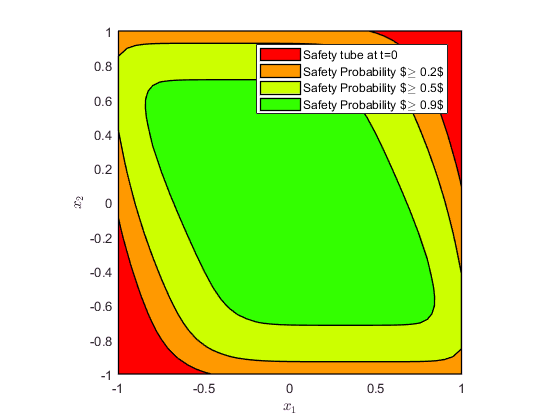

hold on;
plot([safety_tube1(1), poly_array1])
xlabel('$x_1$','interpreter','latex');
ylabel('$x_2$','interpreter','latex');
box on
axis(axis_vec1)
axis equal
legend(legend_str)

# Case 2: Terminal hitting-time stochastic reach-avoid  (Constant safety sets uptil time horizon - 1 and a different target set at time horizon)

## Setup the time-varying safety tube

The advantage of safety tube is that it allows for problem formulations in which we would like to reach a moving target.

## Setup the target and safe sets

safe_set = Polyhedron('lb', [-1, -1], 'ub', [1, 1]);
target_set = Polyhedron('lb', [-0.5, -0.5], 'ub', [0.5, 0.5]);
axis_vec2 = [-1 1 -1 1];

## Setup the safety tube

Safety tube is a generalization of the reach problem. The reach avoid safety-tube is created by setting the first $N-1$ sets in the tube as the `safe_set` and the final set as the `target_set`.

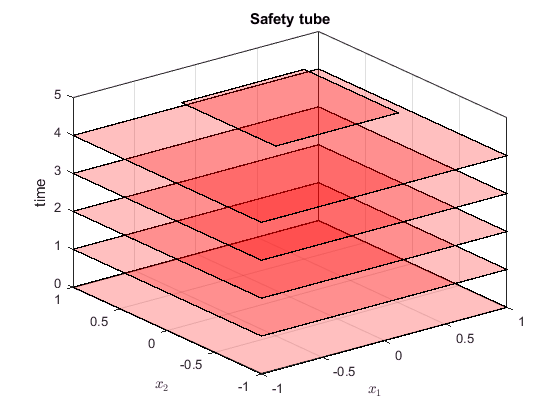

% time horizon
N = 5;
% in target tube for the viability problem is equivalent to a tube of repeating
% safe sets
safety_tube2 = TargetTube('reach-avoid', safe_set, target_set, N);

% Plotting of safety tube
figure()
hold on    
for time_indx=0:N
    safety_tube_at_time_indx = Polyhedron('H',[safety_tube2(time_indx+1).A,zeros(size(safety_tube2(time_indx+1).A,1),1), safety_tube2(time_indx+1).b], 'He',[0 0 1 time_indx]);
    plot(safety_tube_at_time_indx, 'alpha',0.25);
end
axis([axis_vec2 0 N])
box on;
grid on;
xlabel('$x_1$','interpreter','latex');
ylabel('$x_2$','interpreter','latex');
zlabel('time');
title('Safety tube');

## Dynamic programming solution on safety tube

tic;
[prob_x2, cell_of_xvec_x2] = SReachDynProg('term', sys, dyn_prog_xinc, dyn_prog_uinc, safety_tube2);
toc

Elapsed time is 3.028386 seconds.


## Visualization of the value function at t=0 (safety probability)

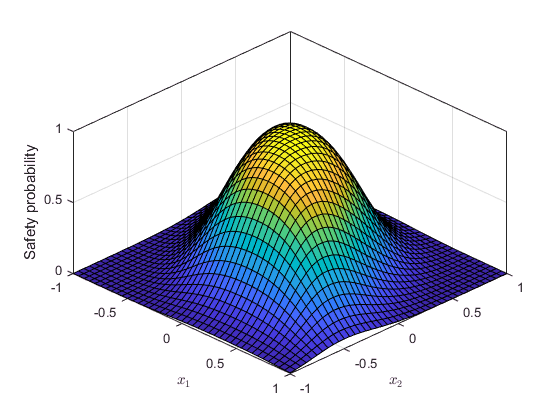

figure();
x1vec = cell_of_xvec_x2{1};
x2vec = cell_of_xvec_x2{2};
axis([axis_vec2 0 N]);
surf(x1vec,x2vec,reshape(prob_x2,length(x2vec),length(x1vec)));
xlabel('$x_1$','interpreter','latex');
ylabel('$x_2$','interpreter','latex');
zlabel('Safety probability')
box on
view(45, 45)

## Visualization of the safe initial sets --- Superlevel sets of safety probability

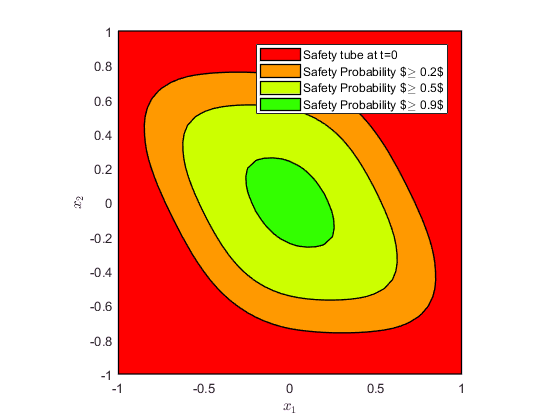

figure();
poly_array2 = getDynProgLevelSets2D(cell_of_xvec_x2, prob_x2, reach_set_thresholds, safety_tube2);
hold on;
plot([safety_tube2(1) poly_array2])
box on
xlabel('$x_1$','interpreter','latex');
ylabel('$x_2$','interpreter','latex');
axis(axis_vec2);
box on
axis equal
legend(legend_str)

# Case 3: Time-varying safety sets

## Setup the time-varying safety tube

The advantage of safety tube is that it allows for problem formulations in which we would like to reach a moving target.

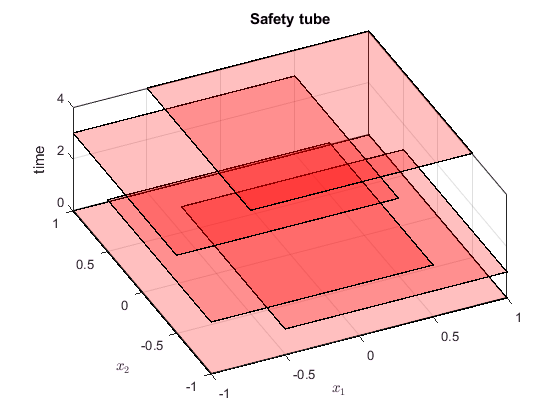

safety_tube3 = TargetTube(Polyhedron('lb', [-1, -1], 'ub', [1, 1]), ...
    Polyhedron('lb', [-0.5, -1], 'ub', [1, 0.5]),...
    Polyhedron('lb', [-1, -1], 'ub', [0.5, 0.5]), ...
    Polyhedron('lb', [-1, -0.5], 'ub', [0.5, 1]), ...
    Polyhedron('lb', [-0.5, -0.5], 'ub', [1, 1]));
axis_vec3 = [-1 1 -1 1];
N=length(safety_tube3)-1;
% Plotting of safety tube
figure()
hold on    
for time_indx=0:N
    safety_tube_at_time_indx = Polyhedron('H',[safety_tube3(time_indx+1).A,zeros(size(safety_tube3(time_indx+1).A,1),1), safety_tube3(time_indx+1).b], 'He',[0 0 1 time_indx]);
    plot(safety_tube_at_time_indx, 'alpha',0.25);
end
axis([axis_vec3 0 N]);
box on;
grid on;
xlabel('$x_1$','interpreter','latex');
ylabel('$x_2$','interpreter','latex');
zlabel('time');
title('Safety tube');
view([-25 60]);

## Dynamic programming solution on safety tube

tic;
[prob_x3, cell_of_xvec_x3] = SReachDynProg('term', sys, dyn_prog_xinc, dyn_prog_uinc, safety_tube3);
toc

Elapsed time is 2.943270 seconds.


## Visualization of the value function at t=0 (safety probability)

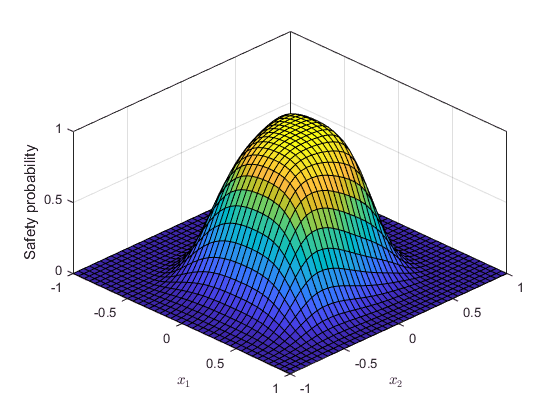

figure();
x1vec = cell_of_xvec_x3{1};
x2vec = cell_of_xvec_x3{2};
axis([axis_vec3 0 N]);
surf(x1vec,x2vec,reshape(prob_x3,length(x2vec),length(x1vec)));
xlabel('$x_1$','interpreter','latex');
ylabel('$x_2$','interpreter','latex');
zlabel('Safety probability')
box on
view(45, 45)

## Visualization of the safe initial sets --- Superlevel sets of safety probability

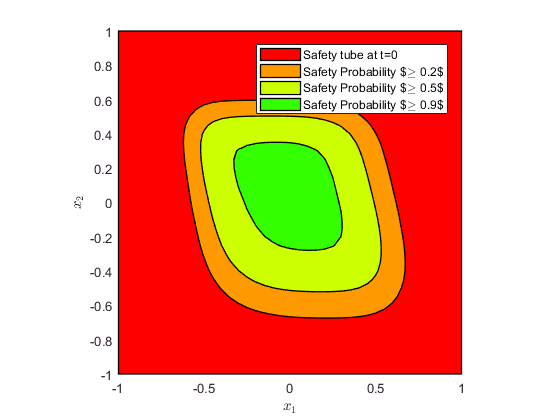

figure();
poly_array3 = getDynProgLevelSets2D(cell_of_xvec_x3, prob_x3, reach_set_thresholds, safety_tube3);
hold on;
plot([safety_tube3(1) poly_array3])
box on
xlabel('$x_1$','interpreter','latex');
ylabel('$x_2$','interpreter','latex');
axis(axis_vec3);
box on
axis equal
legend(legend_str)

# Case 4: First-hitting time stochastic reach-avoid problem

Define the double integrator with larger sampling time.

T = 0.25;

% define the system
sys = LtiSystem('StateMatrix', [1, T; 0, 1], ...
    'InputMatrix', [T^2/2; T], ...
    'InputSpace', Polyhedron('lb', -0.1, 'ub', 0.1), ...
    'DisturbanceMatrix', eye(2), ...
    'Disturbance', StochasticDisturbance('Gaussian', zeros(2,1), 0.001*eye(2)));
%% Setup the dynamic programming and visualization parameters

dyn_prog_xinc = 0.025;
dyn_prog_uinc = 0.1;
reach_set_thresholds = [0.2 0.5 0.9];
safe_set = Polyhedron('lb', [-1, -1], 'ub', [1, 1]);
% time horizon
N = 5;
% in target tube for the viability problem is equivalent to a tube of repeating
% safe sets
safety_tube4 = TargetTube('viability', safe_set, N);

## Setup the time-varying safety tube

The advantage of safety tube is that it allows for problem formulations in which we would like to reach a moving target.

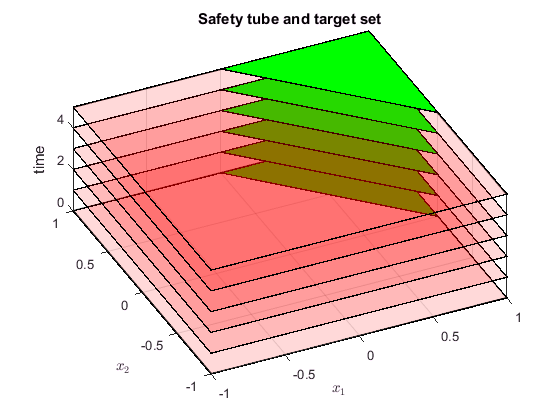

target_set4 = Polyhedron('H',[-1 -1 -1]).intersect(safety_tube1(1));

N=length(safety_tube4)-1;
% Plotting of safety tube and target sets
figure()
hold on    
for time_indx=0:N
    target_set_at_time_indx = Polyhedron('H',[target_set4.A,zeros(size(target_set4.A,1),1), target_set4.b], 'He',[0 0 1 time_indx]);
    plot(target_set_at_time_indx, 'color','g');
    safety_tube_at_time_indx = Polyhedron('H',[safety_tube4(time_indx+1).A,zeros(size(safety_tube4(time_indx+1).A,1),1), safety_tube4(time_indx+1).b], 'He',[0 0 1 time_indx]);
    plot(safety_tube_at_time_indx, 'alpha',0.15,'color','r');
end
axis([axis_vec1 0 N]);
box on;
grid on;
xlabel('$x_1$','interpreter','latex');
ylabel('$x_2$','interpreter','latex');
zlabel('time');
title('Safety tube and target set');
view([-25 60]);

## Dynamic programming solution on safety tube

tic;
[prob_x4, cell_of_xvec_x4] = SReachDynProg('first', sys, dyn_prog_xinc, dyn_prog_uinc, safety_tube4, target_set4);
toc

Elapsed time is 17.175079 seconds.


## Visualization of the value function at t=0 (safety probability)

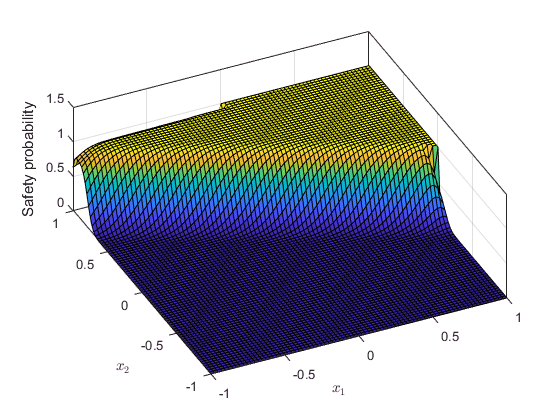

figure();
x1vec = cell_of_xvec_x4{1};
x2vec = cell_of_xvec_x4{2};
axis([axis_vec1 0 N]);
prob_x4_mat = reshape(prob_x4,length(x2vec),length(x1vec));
surf(x1vec,x2vec,prob_x4_mat);
xlabel('$x_1$','interpreter','latex');
ylabel('$x_2$','interpreter','latex');
zlabel('Safety probability')
box on
view([-25 60]);

## Visualization of the safe initial sets --- Superlevel sets of safety probability

We can't use getDynProgLevelSets2D here since the level sets are no longer guaranteed to be convex.

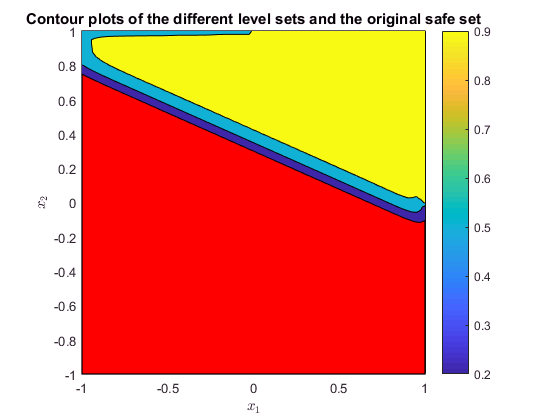

figure();
plot(safety_tube4(1));
hold on
contourf(x1vec,x2vec, prob_x4_mat, reach_set_thresholds);
colorbar;
hold on;
box on
xlabel('$x_1$','interpreter','latex');
ylabel('$x_2$','interpreter','latex');
axis(axis_vec1);
box on
axis equal
title('Contour plots of the different level sets and the original safe set');